# Authors: Marta Barriendos & Ana Garcia Armada, Univesidad Carlos III de Madrid

# 6G Waveforms Proposals

## Introduction

In this notebook, we begin exploring key technologies that are shaping the future of wireless communication, particularly in the context of **6G** networks. The focus is on advanced modulation techniques that aim to improve spectral efficiency and reduce power consumption, two critical challenges for next-generation systems.

We will first introduce the fundamental concepts behind **6G** and why new waveform designs are necessary. Then, we will delve into two promising techniques: **Constant Envelope OFDM (CE-OFDM)** and **Frequency Modulated OFDM (FM-OFDM)**. As well as into OTFS technique, that is a completely different approach. 

This first module will primarily focus on explaining and analyzing **CE-OFDM** and **FM-OFDM** individually, laying the foundation for a later comparison between the two methods based on their performance and practical advantages.

## Index

- Introduction to 6G

- Constant Envelope OFDM (CE-OFDM)

- Frequency modulated OFDM (FM-OFDM)

- Orthogonal Time Frequency Space (OTFS)

## 1. Introduction to 6G

At the end of 2023, 3GPP committed to the development of the sixth-generation mobile system. Right now, the 6G is entering the pre-standardization phase.

Remembering the last generations, the ITU has designated 6G as IMT-2030, with 5G referred to as IMT-2020, 3G as IMT-2000, and 4G as IMT Advanced.

To understand the process that is being followed for the 6G development, the ITU has defined a high level overview of the different steps that will take to define IMT-2030 (6G), that can be seen in the image below.

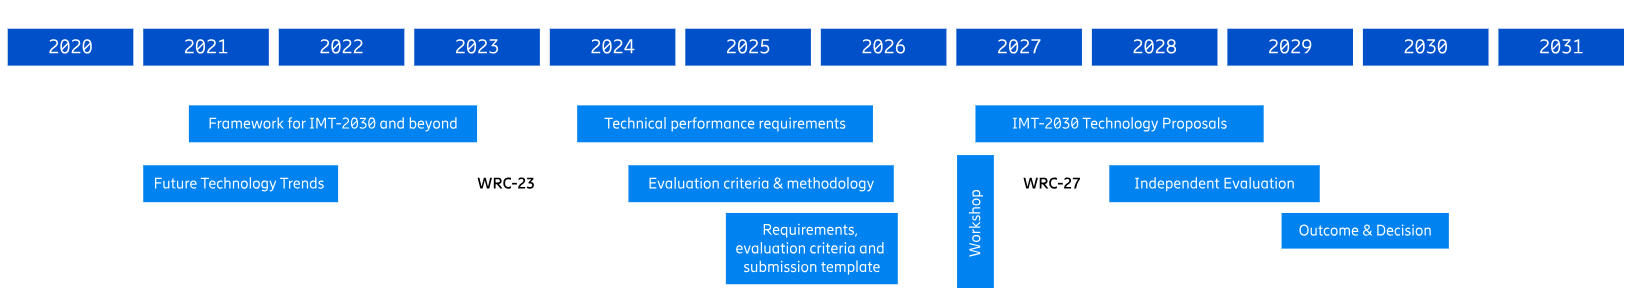

*(https://www.ericsson.com/en/blog/2024/3/6g-standardization-timeline-and-technology-principles)*

Along this module, we are going to propose different implementations for the 6G waveforms, focusing on the three main objectives that we are willing to achieve with 6G:

- Operating at even **higher frequencies** than those already used in 5G.

- Functioning at movement speeds of up to **1000 km/h**.

- Providing **universal coverage**, reaching areas that currently lack connectivity.

In 6G, we continue to use **OFDM modulation** primarily because its **time-frequency grid** is essential for scheduling users. Manufacturers have been working with this system for a long time, refining and optimizing it. They have achieved efficient multiplexing of multiple users, and they are reluctant to change a well-established approach.

Additionally, OFDM ensures **backward compatibility** with **4G and 5G**, allowing us to maintain the same scheduling mechanisms that are already well understood and widely implemented. This continuity helps avoid unnecessary disruptions while leveraging existing infrastructure and expertise.

However, OFDM is very problematic for achieving the 3 main objectives previously commented. The reason is that **OFDM has high power peaks**, which result in poor amplification. This issue worsens at higher frequencies, where technology is less developed. Additionally, high frequencies require greater amplification due to higher signal losses. If amplification is limited, coverage becomes a challenge. Moreover, OFDM is highly sensitive to signal variations, making mobility another concern.

Therefore, although we want to use OFDM as base idea, we need to make some changes to the traditional OFDM signals, which is why **other alternatives are being considered. **For this module we are considering two options:

- **CE-OFDM (Constant Envelope OFDM):**  Constant envelope OFDM (CE-OFDM) transforms the OFDM signal, by way of phase modulation, to a signal designed for efficient power amplification. In fact, CE-OFDM is shown to achieve good performance in dense multipath. 

- **FM-OFDM (Frequency-Modulated OFDM):** By frequency modulating an OFDM signal and further defining a suitable cutoff subcarrier, a constant-envelope waveform is generated, ensuring a low Peak to Average Power Ratio, which exhibits strong robustness not only to Doppler, but also to phase noise and carrier frequency offsets.

## 2. Constant Envelope OFDM (CE-OFDM)

This implementantion is essentially standard OFDM, but instead of transmitting it directly, it modifies the carrier phase. 

If we define the OFDM signal as "***ofdm***". The transmitted signal becomes $e^{\textrm{j2}\pi f\times \textrm{ofdm}}$, and, removing the carrier component ($e^{\textrm{j2}\pi f}$ ), we get the modified OFDM signal. As a consequence, the signal now has a constant envelope. However, for this approach to work, the OFDM signal  "***ofdm***" must be real, as the phase $2\times \pi \times f\times \textrm{ofdm}$ cannot be complex, which we will take into consideration in the following code's sections.

The implementation will be made follwing the steps of the scheme below. 

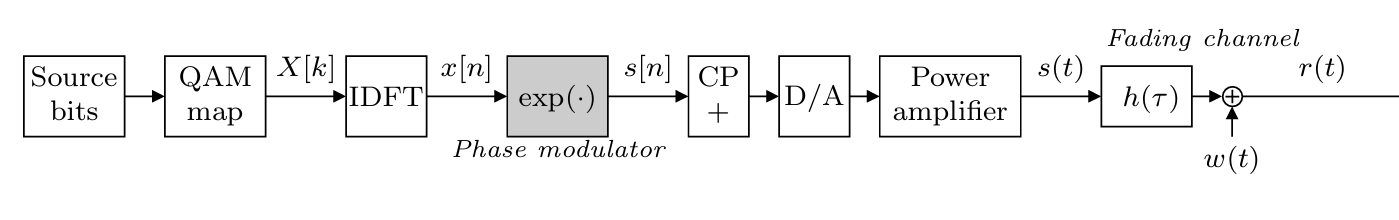

(Constant Envelope OFDM, *Steve C. Thompson, Ahsen U. Ahmed, John G. Proakis, James R. Zeidler and Michael J. Geile*)

Therefore, analysing the scheme, it is clear that in order to implement the CE-OFDM signal, we can reuse the OFDM implemenation code of the first module, where the first step is to define the corresponding parameters, including the length of the cyclic prefix (*Ng*), and the guardabands (*fg_1* and *fg_2*). 

N_OFDM=2048;
Ng=1/8*N_OFDM; 
fg_1=171;
fg_2=172;
Fs=20; %MHz
N_symb=100;

We already have everything prepared to create the OFDM signal. For doing this process, first we must create a zero vector with the proper dimensions, so, since the number of symbols we want to simulate is *N_symb* and each symbol has *N_OFDM* total subcarriers (including both the effective ones and the guard bands) plus the number of samples chosen for the cyclic prefix (*Ng*):

signal=zeros(1,N_symb*(N_OFDM+Ng));                         

The next step is to fill the zero signal created above. However, as it has been explained before, it is necessary to create a real OFDM signal, so that it can be phase-modulated without causing distortions. 

Since OFDM symbols are typically defined in the **frequency domain**, we begin by generating **QPSK symbols** for the **positive frequencies**, excluding the **DC** (0 Hz) and **Nyquist** frequencies. For doing this, we create the phase and quadrature components, that together create the signal *qpsk_data*.

To ensure that the **IFFT output is real**, we enforce **Hermitian symmetry**, meaning that the negative frequency components are the **complex conjugate mirror** of the positive frequency components. This way, the first *N_OFDM/2* QPSK symbols will be allocated in the first part of the signal *qpsk_ini*, while the same QPSK symbols but conjugate will be allocated in the final part of the signal *qpsk_ini*.

It is important to notice that, the **DC Component** (*qpsk_ini(1) ) *is randomly set to **±1**, ensuring a real value at 0 Hz, and the **Nyquist Component** (*qpsk_ini(N_OFDM/2 + 1)* ) is also set to **±1**, ensuring real values at the highest frequency before aliasing. This is very important, since in order to get a Hermitian symmetry in the frequency domain, we don't only need to mirror positive frequency components by negative frequency components as complex conjugates, but also the  **DC component** (index 0) and the **Nyquist component** (index N_OFDM/2), which don’t have negative counterparts (they’re at the boundaries of the spectrum), must be real to guarantee the IFFT produces a real-valued time-domain signal and avoid asymmetries.

Then, we just need to use the function c*onj(fliplr()), *to complex conjugate the positive frequencies in reverse order (for the last *N_OFDM/2* positions) to maintain **Hermitian symmetry.**

Finally, we just need to apply to the resultant signal (*qpsk_ini*) the **Inverse Fast Fourier Transform (IFFT)**, converting the **frequency-domain** representation into the **time domain**. 

% Generate QPSK symbols for positive frequencies (excluding DC and Nyquist)
num_data_symbols = N_OFDM/2 - 1;
i = sign(rand(1, num_data_symbols) - 0.5);
q = sign(rand(1, num_data_symbols) - 0.5);
qpsk_data = i + 1j * q;

% Allocate OFDM array with Hermitian symmetry
qpsk_ini = zeros(1, N_OFDM);

% DC component (real)
qpsk_ini(1) = sign(rand(1) - 0.5); % -1 or 1

% Positive frequencies (indices 2 to N_OFDM/2)
qpsk_ini(2 : N_OFDM/2) = qpsk_data;

% Nyquist component (real)
qpsk_ini(N_OFDM/2 + 1) = sign(rand(1) - 0.5); % -1 or 1

% Negative frequencies: conjugate and reverse positive frequencies
qpsk_ini(N_OFDM/2 + 2 : end) = conj(fliplr(qpsk_data));


Max imaginary part: 0


% Perform N_OFDM-point IFFT to get real signal
ofdm = N_OFDM*ifft(qpsk_ini, N_OFDM);

% Verify realness (imaginary part ~0)
max_imag = max(abs(imag(ofdm)));
disp(['Max imaginary part: ', num2str(max_imag)]);

As we can see, from the previous code, the resultant signal "*ofdm*" has a null imaginary part, in fact, its maximum value is 0. However, this can be verified by plotting together the real and imaginary part of the final *ofdm* signal, where clearly, the imaginary part corresponds to a line in zero, as we were expecting.

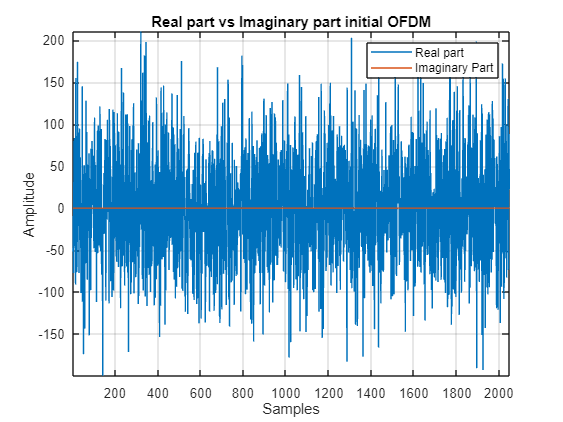

figure()
plot(real(ofdm))
hold on
plot(imag(ofdm))

xlabel("Samples")
ylabel("Amplitude")
title("Real part vs Imaginary part initial OFDM")
legend("Real part","Imaginary Part")
grid on
axis tight;

Once we have the real OFDM signal prepared, the next step is to do the phase modulation. The **input OFDM signal is real**, meaning each value represents a phase shift in the complex plane, while the output now will be a **purely phase-modulated signal**, maintaining a **constant envelope**. 

Moreover, we are adding a modulation index, ***m***, which basically is a phase rotation factor that controls the amount of phase shift per sample. Initially, we fix a value of 1, which means that the phase follows the original signal directly, however, if ***m*** increases, the phase variation will increase, potentially improving spectral efficiency but also increasing complexity.

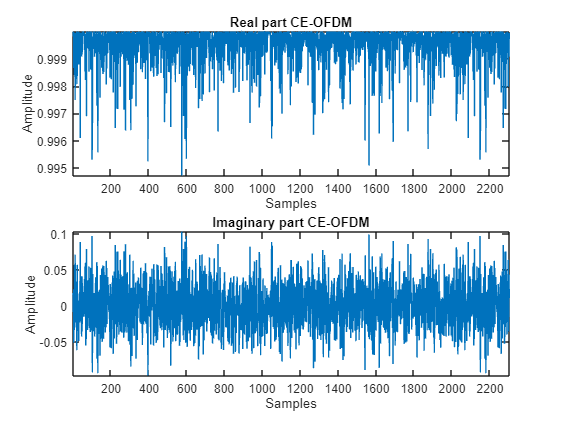

% Apply the exponential phase shift e^(j * m * ofdm)
m = 1;  % Phase rotation factor, can adjust based on the desired rotation
ce_ofdm = exp(1j * m.*ofdm/N_OFDM );  % Apply phase shift to each symbol in time domain

% Add the cyclic prefix
ce_ofdm = [ce_ofdm(N_OFDM - Ng + 1 : N_OFDM), ce_ofdm];

figure()
subplot(2,1,1)
plot(real(ce_ofdm))
title("Real part CE-OFDM")
xlabel("Samples")
ylabel("Amplitude")
axis tight

subplot(2,1,2)
plot(imag(ce_ofdm))
xlabel("Samples")
ylabel("Amplitude")
title("Imaginary part CE-OFDM")
axis tight

Now, once we have the final CE-OFDM Signal generated ***ce_ofdm***, we can represent its envelope, to verify the constant behaviour we were expecting.

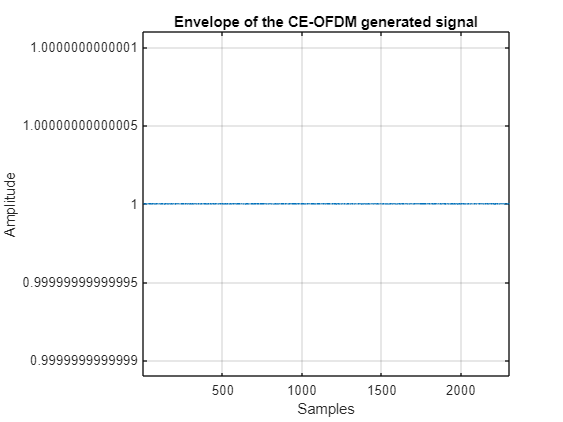

figure()

plot(abs(ce_ofdm))
title("Envelope of the CE-OFDM generated signal")
xlabel("Samples")
ylabel("Amplitude")
grid on;
axis tight;

At this point, we already have one **CE-OFDM symbol**, so now, we just need to include the previous code blocks into a loop, to generate a finite number of symbols. Moreover, to assess the impact of the modulation factor ***m*** in the spectrum, we are going to generate two CE-OFDM signals with two extreme values of this factor.

m_low=0.001/(2*pi);
m_large=1/(2*pi);
for symb=1:N_symb   

    % Generate QPSK symbols for positive frequencies (excluding DC and Nyquist)
    i = sign(rand(1, num_data_symbols) - 0.5);
    q = sign(rand(1, num_data_symbols) - 0.5);
    qpsk_data = i + 1j * q;
    
    % Allocate OFDM array with Hermitian symmetry
    qpsk_ini = zeros(1, N_OFDM);
    
    % DC component (real)
    qpsk_ini(1) = sign(rand(1) - 0.5); % -1 or 1
    
    % Positive frequencies (indices 2 to N_OFDM/2)
    qpsk_ini(2 : N_OFDM/2) = qpsk_data;
    
    % Nyquist component (real)
    qpsk_ini(N_OFDM/2 + 1) = sign(rand(1) - 0.5); % -1 or 1
    
    % Negative frequencies: conjugate and reverse positive frequencies
    qpsk_ini(N_OFDM/2 + 2 : end) = conj(fliplr(qpsk_data));
    
    % Perform N_OFDM-point IFFT to get real signal
    ofdm = N_OFDM*ifft(qpsk_ini, N_OFDM);
    
    % Apply the exponential phase shift e^(j * m * ofdm)
    ofdm_low = exp(1j *2*pi* m_low.*ofdm/sqrt(N_OFDM) );  % Apply phase shift to each symbol in time domain
    ofdm_large = exp(1j *2*pi* m_large.*ofdm/sqrt(N_OFDM));  % Apply phase shift to each symbol in time domain
    % Add the cyclic prefix
    ofdm_low = [ofdm_low(N_OFDM - Ng + 1 : N_OFDM), ofdm_low]; 
    ofdm_large = [ofdm_large(N_OFDM - Ng + 1 : N_OFDM), ofdm_large]; 

    % Store the transmitted signal
    signal_low(1, (symb - 1) * (N_OFDM + Ng) + 1 : symb * (N_OFDM + Ng)) = ofdm_low;
    signal_large(1, (symb - 1) * (N_OFDM + Ng) + 1 : symb * (N_OFDM + Ng)) = ofdm_large;


end

We can represent again the real an imaginary part of the CE-OFDM signal, but in this case, it contains a higher number of symbols, not just 1. However, in the graph below, we are only going to represent the first two symbols,  to have a clearer version of the generated signal. 

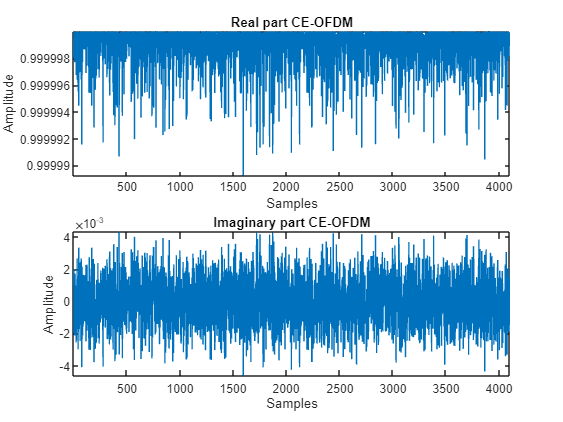

figure()
subplot(2,1,1)
plot(real(signal_low(1:2048*2)))
title("Real part CE-OFDM")
xlabel("Samples")
ylabel("Amplitude")
axis tight

subplot(2,1,2)
plot(imag(signal_low(1:2048*2)))
title("Imaginary part CE-OFDM")
xlabel("Samples")
ylabel("Amplitude")
axis tight

Now, we represent again the envelope of the signal to verify its constant value.

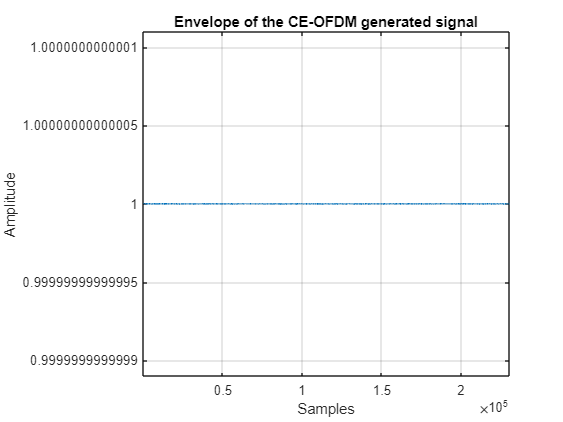

figure()

plot(abs(signal_low))
title("Envelope of the CE-OFDM generated signal") 
xlabel("Samples")
ylabel("Amplitude")
grid on;
axis tight;

Finally, once we have the signal created, we can represent its spectrum, to verify that the CE-OFDM signal that we have created looks great, and in fact, has a different spectrum than the one of the previous OFDM signal, which is proved with the graph below. Moreover, we are going to display two different representations, corresponding to the large and small values of the modulation index ***m***.

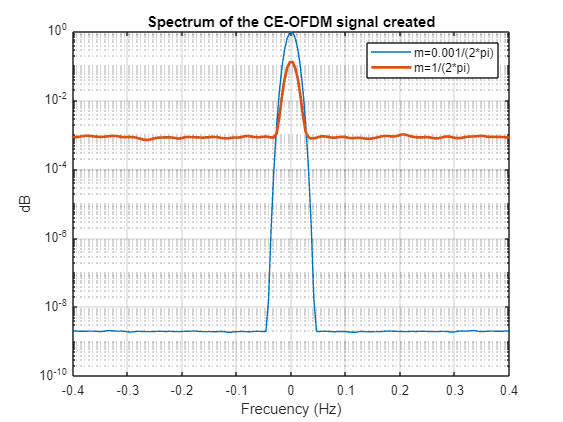

[p_low,f] = pspectrum(signal_low); %Spectrum for the signal with the small value of m 
[p_large,f] = pspectrum(signal_large);%Spectrum for the signal with the large value of m
new_f=f./pi*Fs/2;
figure()
semilogy(new_f,p_low)
hold on
semilogy(new_f, p_large, 'LineWidth', 2);

grid on
legend('m=0.001/(2*pi)','m=1/(2*pi)')
title('Spectrum of the CE-OFDM signal created')
xlabel("Frecuency (Hz)")
ylabel('dB')
xlim([-0.4 0.4])

Analyzing the previous figure, it can be seen how for the modulation factor ***m = 0.001***, the spectrum is more concentrated around the center frequency, showing a narrower bandwidth and significantly lower side lobes, and therefore more spectral efficiency. This is specially useful for minimizing interference with adjacent channels. However, for the case of ***m=1***, the spectrum is more spread out, having a wider main lobe and higher side lobes. It shows a more uniform power distribution across the range of frequencies. This suggest an increment of the bandwidth usage and a higher spectral leakage. 

Consequently, it is clear that the **choice of modulation** factor in CE-OFDM has a significant impact in the spectrum of the signal. A lower modulation factor will provide better spectral efficiency with the use of a lower bandwidth. However, a higher modulation factor generates a broader spectrum, with a largest bandwidth, which is beneficial if we want robustness and resilience instead of use as low bandwidth as possible.